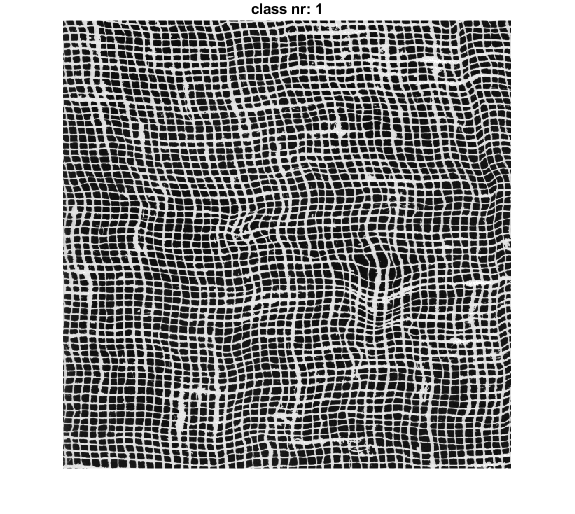

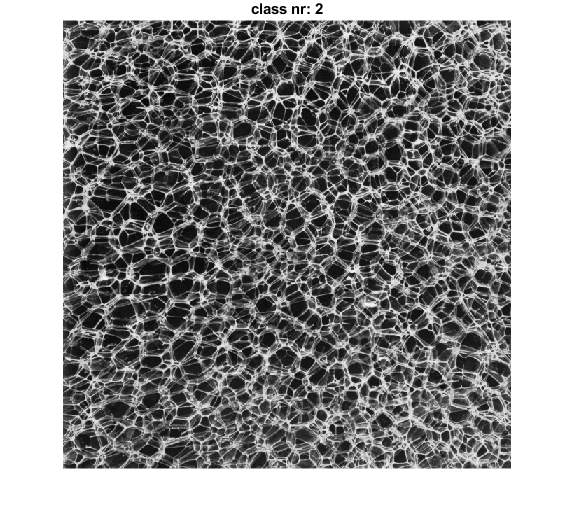

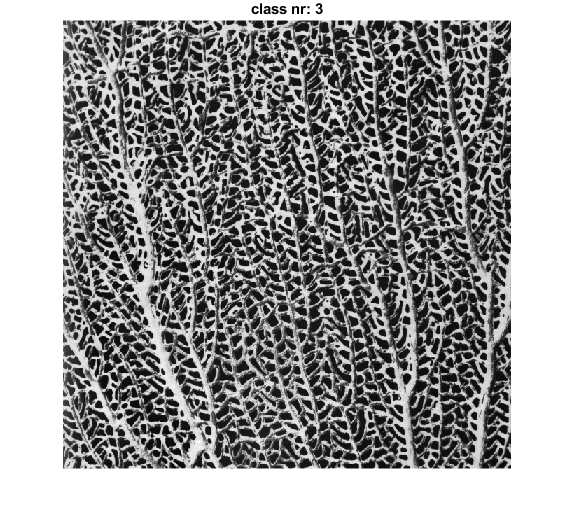

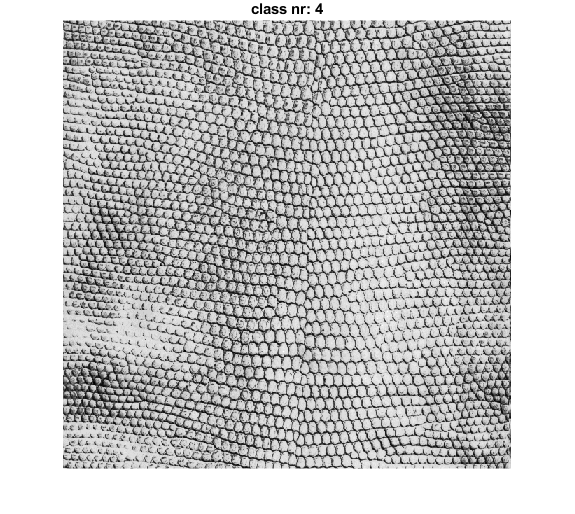

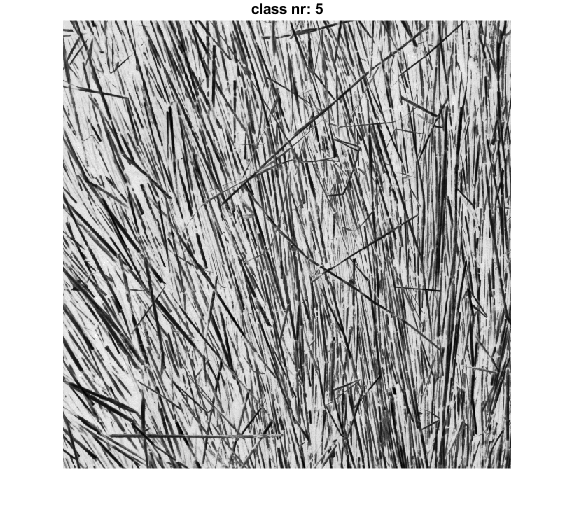

% demo for classification
close all
clc
clear


%% load all  5 images
all_img = {};
for ii=1:5
    all_img{ii} = im2double(imread(['data/textures/texture_',num2str(ii),'.gif']));
    figure(ii), imshow(all_img{ii}), title(['class nr: ', num2str(ii)])
end



%% dictionaries learning
% number of nonzero components
L = 4;

% patch size
p= 15;

% number of atom of each subdictionary (dictionary for a class)

natom_sub = round(p^2*1.5);
%natom_sub = 100;
% number of patches used for learning each dictionary
npatch = 500;


%KSVD is used for dictionary learning because it is faster than mod
% number of iteration of ksvd
niter = 5;
algorithm_ksvd = "OMP_Chol";

D = [];



%% Learn 5 different dictionaries and stack them into a matrix D 
for ii=1:5
    img = all_img{ii};
    % select only the left half of each image for dictoinary learning
    half_img = img(:,1:end/2);
    %half_img_reduced = zeros(size(half_img)-p+1);
    % extract random patches 
    indexes = randperm((size(half_img,1)-p)*(size(half_img,2)-p), npatch);
    S = zeros(p*p,npatch);
    % PREPROCESSING: exclude black and white patches from S
    thr_black_patches = 0.06;
    thr_white_patches = 0.94;
    v = median(S,1);
    S = S(:,v > thr_black_patches);
    v = median(S,1);
    S = S(:,v < thr_white_patches);

    for k=1:npatch
        [row, col] = ind2sub(size(half_img)-p+1, indexes(k));
        S(:,k) = reshape(half_img(row:row+p-1,col:col+p-1),[],1);
    end
    
    % remove the mean value from each patch
    S = S - mean(S,1);
    % learn dictionary by ksvd (inizialized by normalized random noise)
    tic
    %D_new = mod_dl(S, natom_sub, lambda, niter, algorithm_ksvd);
    D_new = ksvd(S, natom_sub, L, niter, algorithm_ksvd);
    toc
    % concantenate the subdictionary
    
    D = [D, D_new];
end

Using Ksvd with OMP_Chol...


Elapsed time is 2.923921 seconds.


Using Ksvd with OMP_Chol...


Elapsed time is 2.112124 seconds.


Using Ksvd with OMP_Chol...


Elapsed time is 2.214567 seconds.


Using Ksvd with OMP_Chol...


Elapsed time is 2.247208 seconds.


Using Ksvd with OMP_Chol...


Elapsed time is 2.390373 seconds.


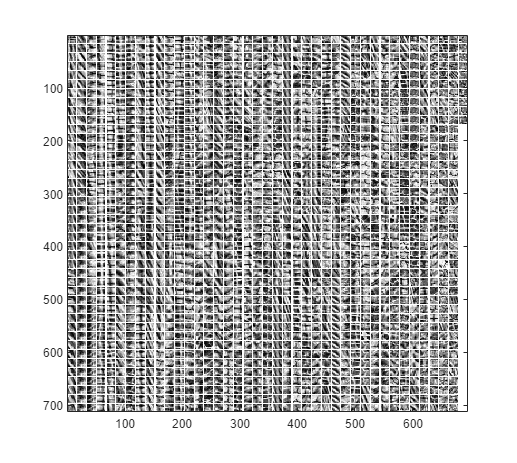

 
%%
show_dictionary(D)

%% classification
lambda = 0.08;
% number of patch for each class
npatch = 500;

% extratc the patch from each image
labels = [];
S = [];
for ii=1:5
    img = all_img{ii};
    
    % select the right half of each image
    half_img = img(:,end/2:end);
    % extract random patches
    indexes = randperm((size(half_img,1)-p)*(size(half_img,2)-p), npatch);
    patches_group = zeros(p*p,npatch);
    for k=1:npatch
        [row, col] = ind2sub(size(half_img)-p+1, indexes(k));
        patches_group(:,k) = reshape(half_img(row:row+p-1,col:col+p-1),[],1);
    end
    % concantenate the patches 
    S = [S, patches_group];
    % store the ground truth (the label for all the patches in this
    % iteration is ii)
    labels = [labels, ones(1,npatch)*ii];
end

%  remove the mean value from each testing patch
S = S - mean(S, 1);


% sparse coding of all the test patches
rho = 1;
inverse_matrix = 1/rho * eye(size(D,2)) - 1/rho*D'*((eye(size(D,1))*rho + D*D')\D);
X = zeros(size(D, 2), size(S, 2));
for i=1:size(S,2)
    %ell1 sparse coding
    X(:,i) = ADMM(D,S(:,i), 1, lambda, rho, inverse_matrix,  1e3, 1e-3);
    
    %ell0 sparse coding (i gave it a try, it actually works better and
    %faster
    %X(:,i) = OMP(D, S(:,i), 0.0001, L);
    %X(:,i) = OMP_Chol(S(:,i), D, L, 1e-3); 
end
% classify each patch, computing the residual of each patch w.r.t. to the
% subdictionaries
new_labels=zeros(1,npatch*5);
for i_patch=1:size(S,2)
    err = zeros(1,5);
    for ii =1:5
        % extract the subdictionary Dii
        col = (ii-1)*natom_sub;
        Dii = D(:,(1:natom_sub)+col);
        % extract the coefficients corresponding to atoms of Dii from the sparse representation X
        coeffii = X((1:natom_sub)+col,i_patch);
        % compute the residual w.r.t. to the subdictionary Dii
        err(ii) = norm(Dii*coeffii - S(:,i_patch), 2);
    end
    % assign the label of the dictionary yielding lowest reconstruction error
    [~,new_labels(i_patch)] = min(err);
end

% compute the accuracy of the classifier
%%
accuracy = sum((new_labels == labels))/npatch/5

accuracy = 0.5348

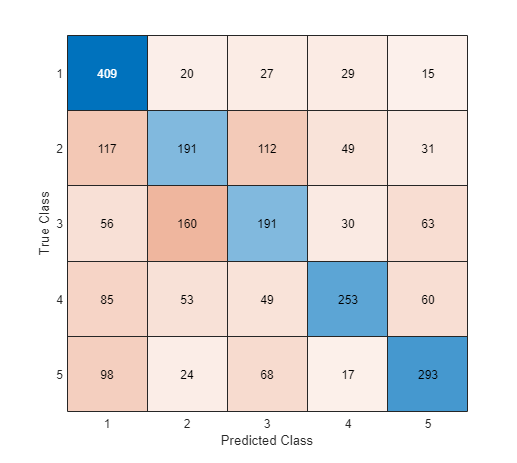

% confusion matrix
confusionchart(confusionmat(labels,new_labels));